HW5P5: 

Bullet 1: 

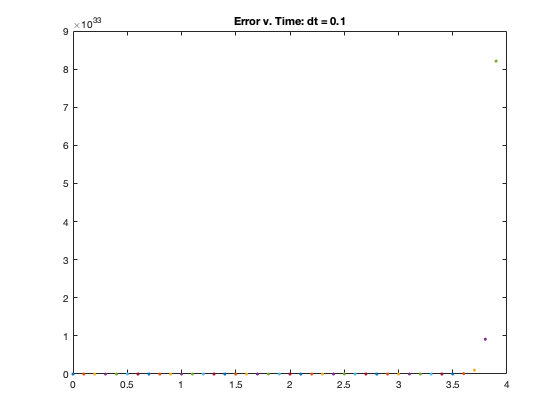

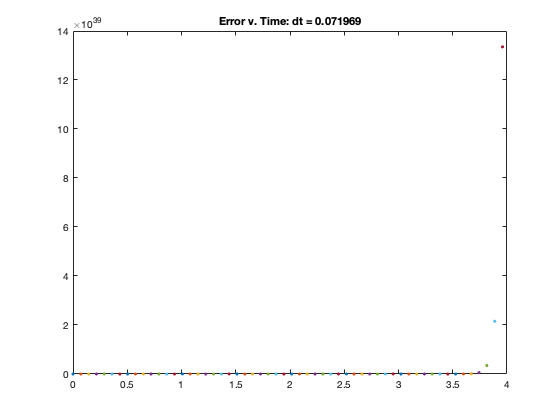

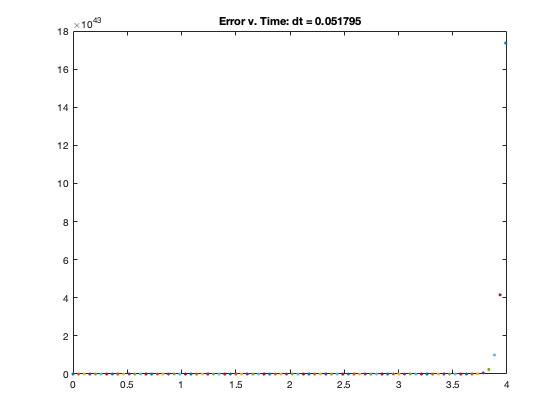

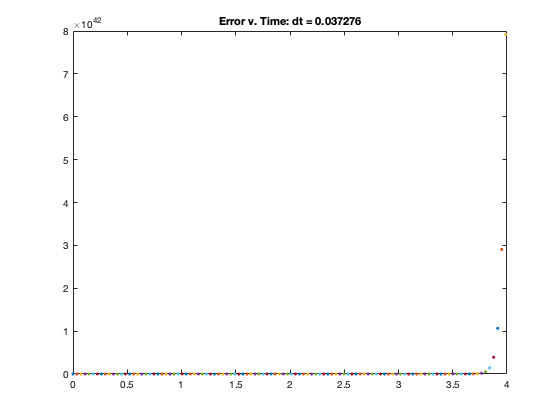

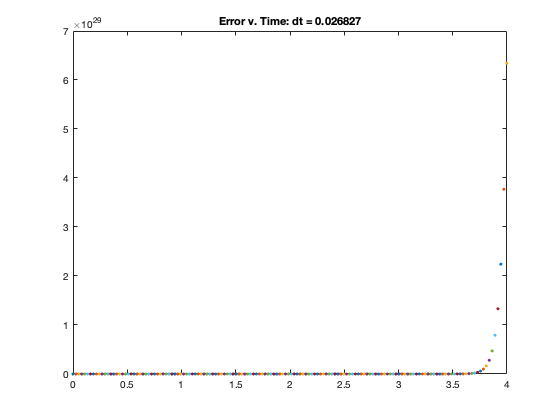

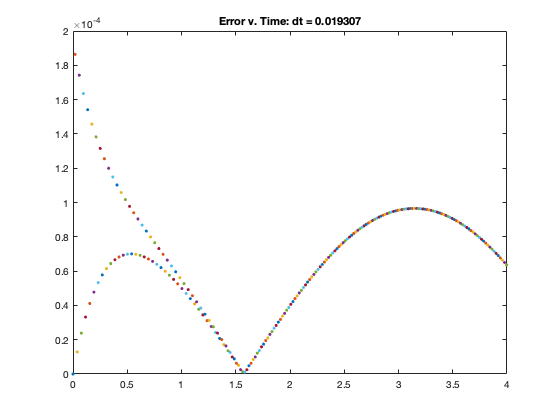

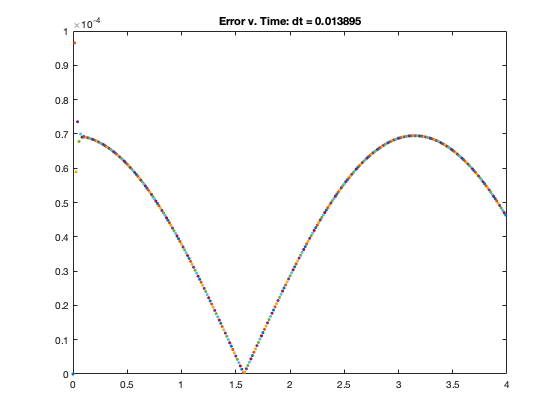

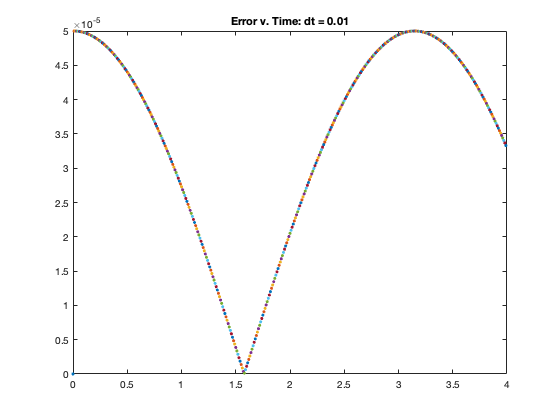

%Delta t vector & Final Time
dt = logspace(-1,-3,15);
T = 4;

%ODE and Constraints
ode = @(u,t) -100*(u -cos(t)) - sin(t);
u0 = 1;

%Actual
act = @(t) cos(t); 

%Error of Each dt
errDt = zeros(T/dt(1,15),15);

%Find Error For Our Choise of Time Step
for i = 1 : length(dt)
    
    %Number of Time Steps
    N = ceil(T/dt(1,i));
    
    %Solution Calculated by F. Eulers
    approxSol = zeros(N,2); 
    
    %Set Initial 
    approxSol(1,1) = 0;
    approxSol(1,2) = u0; 
    
    % Find Approx Sol. 
    for j = 2: N
        
        approxSol(j,1) = approxSol(j-1,1) + dt(1,i); 
        approxSol(j,2) = approxSol(j-1,2) + dt(1,i)*ode(approxSol(j-1,2),approxSol(j-1,1));
    end
    
    %Error Vector
    error = zeros(N,2); 
    
    %Calculate Error
    for j = 1: N
        
        error(j,1) = approxSol(j,1);
        error(j,2) = abs(approxSol(j,2)-act(error(j,1)));
    end
    
    %Save the Data in External Source
    for j = 1: T/dt(1,15)
    
        %If we've saved all the data we have stop
        if(j>N)
            
            break;
        end
        
        errDt(j,i) = error(j,2); 
    end
    
end

%Time Stamps for dt
times = zeros(T/dt(1,15),15);

%Reconstruct Times For Each dt
for i = 1: length(dt);
    
    %Set initial time
    times(1,i) = 0;
   
    %Find Following Times
    for j = 2: nnz(errDt(:,i)) + 1
        
        times(j,i) = times(j-1,i) + dt(1,i);
    end
    
    %Fix Final Step
    times(j+1,i) = 4;
end

%Plot Errors & dts
for i = 1: 15
    
    figure(i);
    
    for j = 1: nnz(errDt(:,i)) + 1
   
        plot(times(j,i),errDt(j,i),'.');
        hold on;
    end
    
    title("Error v. Time: dt = " + dt(1,i));
end

In the Larger Time Steps, We get that the error goes off to inifnity as t -> 4.

Bullet 3: 

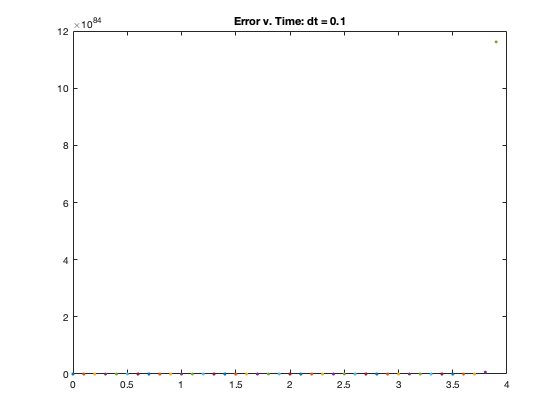

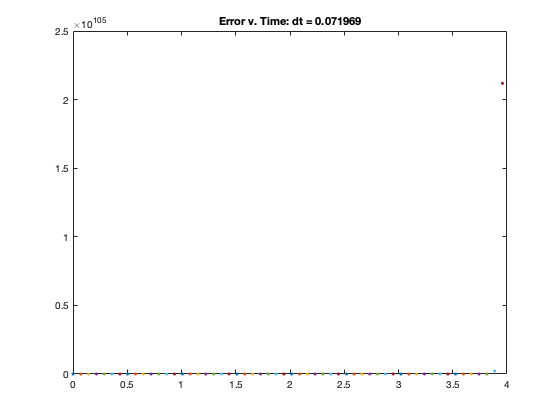

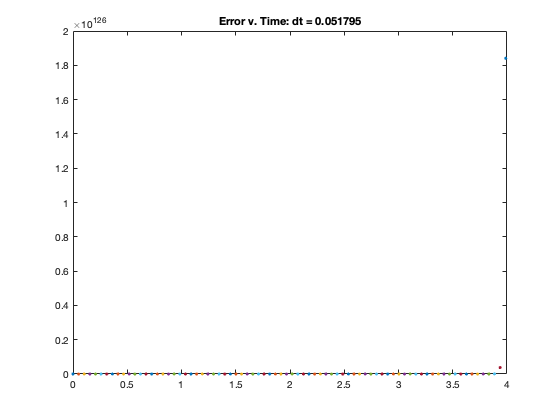

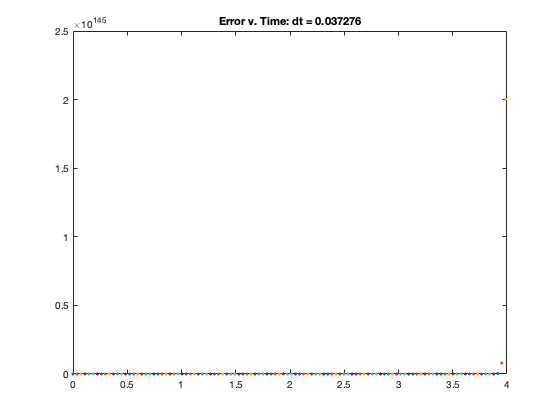

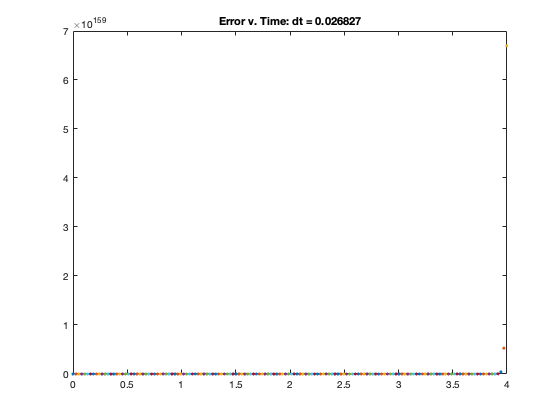

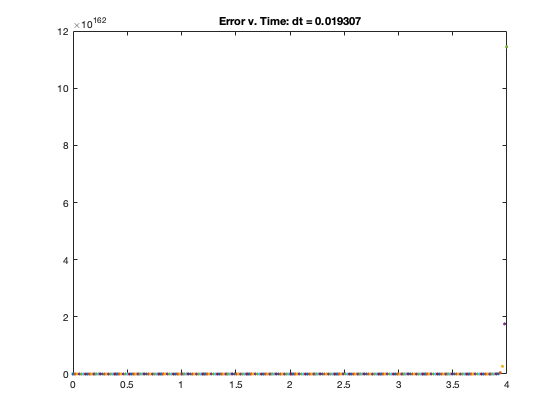

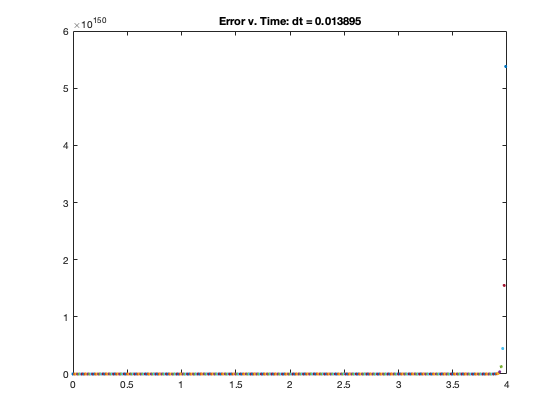

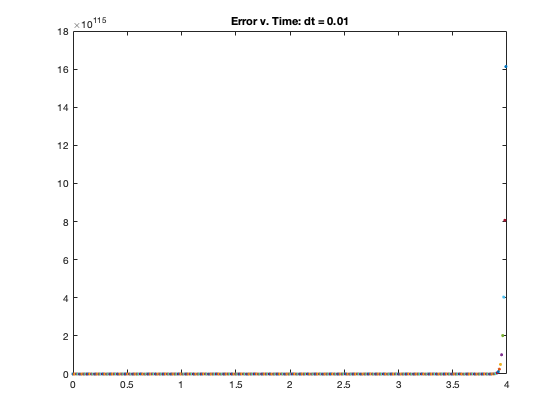

%Delta t vector & Final Time
dt = logspace(-1,-3,15);
T = 4;

%ODE and Constraints
ode = @(u,t) -100*(u -cos(t)) - sin(t);
u0 = 1;

%Actual
act = @(t) cos(t); 

%Error of Each dt
errDt = zeros(T/dt(1,15),15);

%Find Error For Our Choise of Time Step
for i = 1 : length(dt)
    
    %Number of Time Steps
    N = ceil(T/dt(1,i));
    
    %Solution Calculated by F. Eulers
    approxSol = zeros(N,2); 
    
    %Set Initial 
    approxSol(1,1) = 0;
    approxSol(1,2) = u0; 
    
    % Find Approx Sol. 
    for j = 2: N
        
        % Simplification of Method
        term1 = ode(approxSol(j-1,2),approxSol(j-1,1));
        term2 = ode((approxSol(j-1,2) + 4*dt(1,i)*term1),approxSol(j-1,1) + dt(1,i));
        
        approxSol(j,1) = approxSol(j-1,1) + dt(1,i); 
        approxSol(j,2) = approxSol(j-1,2) + (dt(1,i)/2)*(term1 + term2);
    end
    
    %Error Vector
    error = zeros(N,2); 
    
    %Calculate Error
    for j = 1: N
        
        error(j,1) = approxSol(j,1);
        error(j,2) = abs(approxSol(j,2)-act(error(j,1)));
    end
    
    %Save the Data in External Source
    for j = 1: T/dt(1,15)
    
        %If we've saved all the data we have stop
        if(j>N)
            
            break;
        end
        
        errDt(j,i) = error(j,2); 
    end
    
end

%Time Stamps for dt
times = zeros(T/dt(1,15),15);

%Reconstruct Times For Each dt
for i = 1: length(dt)
    
    %Set initial time
    times(1,i) = 0;
   
    %Find Following Times
    for j = 2: nnz(errDt(:,i)) + 1
        
        times(j,i) = times(j-1,i) + dt(1,i);
    end
    
    %Fix Final Step
    times(j+1,i) = 4;
end

%Plot Errors & dts
for i = 1: 15
    
    figure(i + 15);
    
    for j = 1: nnz(errDt(:,i)) + 1
   
        plot(times(j,i),errDt(j,i),'.');
        hold on;
    end
    
    title("Error v. Time: dt = " + dt(1,i));
end

The Trapezoidal Method has a lower region of stability on the interval we're considering. Also the Trapezoidal Method only gets to an accuracey of 10^-3 whereas the forward Euler's Method gets to an accuracy of 10^-6. So Forward Euler's must be more effective on the bounds were considering [0,4]. 